## Shapefile von Boston einlesen


boston_roads = shaperead('boston_roads.shp');
HW_1_2 = shaperead('boston_roads', 'Selector',{@(v1) (v1 < 3) || (v1 == 7), 'CLASS'});
other_3 = shaperead('boston_roads', 'Selector',{@(v1) (v1 == 3), 'CLASS'});
locals_4_5_6 = shaperead('boston_roads', 'Selector',{@(v1) (v1 == 4) || (v1 == 5) || (v1 == 6), 'CLASS'});
% Strassenklassen abspeichern
save('HW_1_2', 'HW_1_2');
save('locals_4_5_6', 'locals_4_5_6');
save('other_3', 'other_3');


## Strassenklassen einfaerben und anzeigen

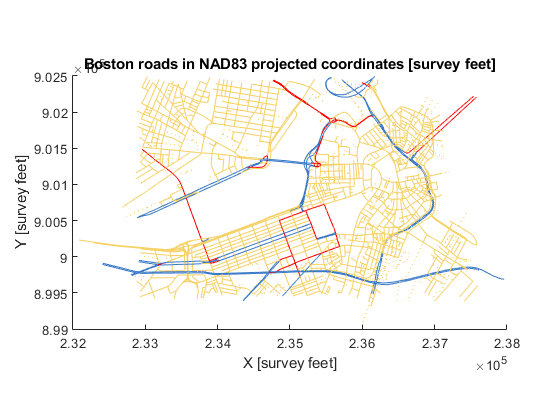


roadColors = ...
makesymbolspec('Line',{'CLASS',1,'Color',[0.22,0.47,0.78]},...
                      {'CLASS',2,'Color',[0.22,0.47,0.78]},...
                      {'CLASS',3,'Color','r'},...
                      {'CLASS',4,'Color',[0.96,0.82,0.4]},...
                      {'CLASS',5,'Color',[0.96,0.82,0.4]},...
                      {'CLASS',6,'Color',[0.96,0.82,0.4],'LineStyle',':'},...
                      {'CLASS',7,'Color',[0.22,0.47,0.78]},...
                      {'Default','Color','k'});
figure
mapshow(boston_roads,'SymbolSpec',roadColors);
title('Boston roads in NAD83 projected coordinates [survey feet]')
xlabel('X [survey feet]')
ylabel('Y [survey feet]')

%mapshow('boston.tif')

## Projizierte Koordinaten in Survey Feet in Meter transformieren und darstellen

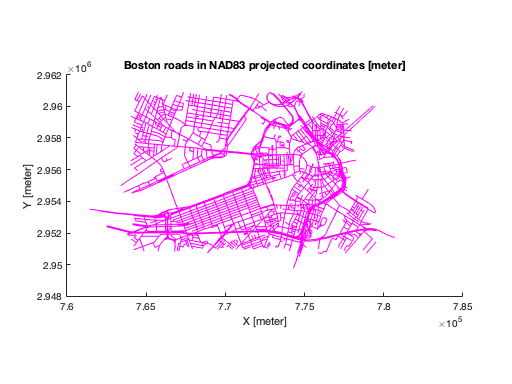


boston_tif = geotiffread('boston.tif');
proj = geotiffinfo('boston.tif');
mstruct = geotiff2mstruct(proj);
x = [boston_roads.X] * unitsratio('survey feet', 'meter');
y = [boston_roads.Y] * unitsratio('survey feet', 'meter');
figure
mapshow(x,y, 'Color','m')
title('Boston roads in NAD83 projected coordinates [meter]')
xlabel('X [meter]')
ylabel('Y [meter]')

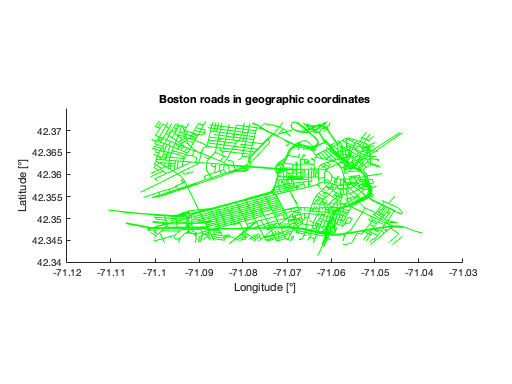

%% X und Y Koordinaten in Laengen- und Breitgrad umrechnen und darstellen
[lat,lon] = projinv(proj,x,y);
figure
geoshow(lat,lon, 'Color', 'g')
title('Boston roads in geographic coordinates')
xlabel('Longitude [°]')
ylabel('Latitude [°]')